clear all
load fisheriris


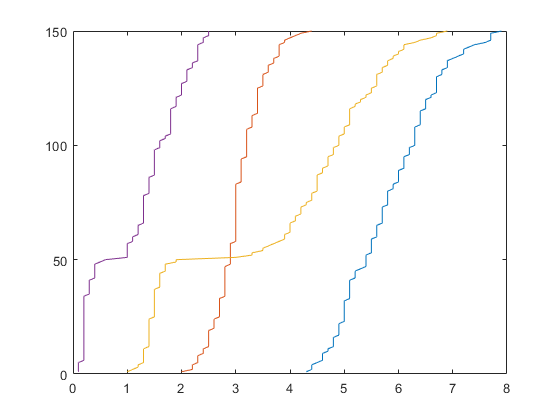

rng('default')
% rand(2,2);
[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexes= randperm(150);

plot(sort(meas()),(1:150))

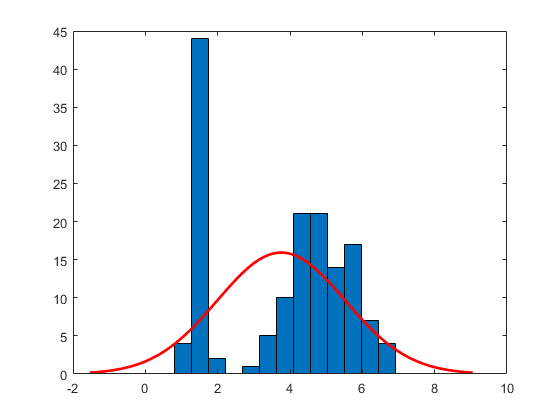

histfit((meas(:,3)))

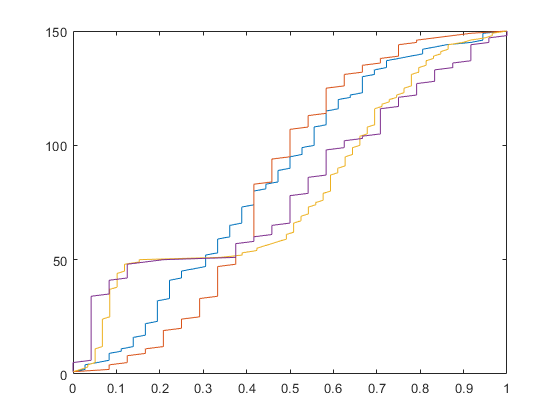


input = normalize(meas(indexes,:),'range');
plot(sort((input)), 1:150)

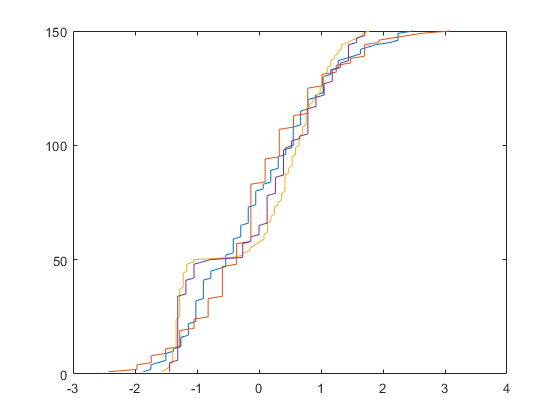


output = y(indexes,:);

input2 = normalize(meas(indexes,:));

g = (1 + exp(-1 * input2)) .^ -1;

plot(sort((input2)), 1:150)

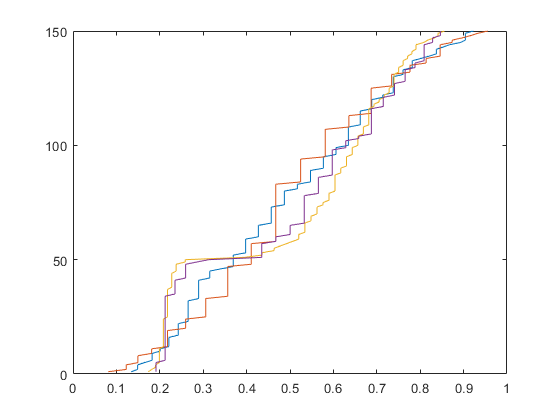

plot(sort((g)), 1:150)


testinput = g((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = g(1:batchsize,:);
out = output(1:batchsize,:);

n = 1;


knots = 10

knots = 10

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);

B=[];
C=[];


% Vandermonde ----------

for i = 1:batchsize
    
    index_a(i)= floor((in(i,1)*knots+(10*knots*eps)))+1;
    index_b(i)= floor((in(i,2)*knots+(10*knots*eps)))+1;
    index_c(i)= floor((in(i,3)*knots+(10*knots*eps)))+1;
    index_d(i)= floor((in(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(in(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(in(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(in(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(in(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,index_a(i):index_a(i)+2) = Ntemp_a;
    N_b(i,index_b(i):index_b(i)+2) = Ntemp_b;
    N_c(i,index_c(i):index_c(i)+2) = Ntemp_c;
    N_d(i,index_d(i):index_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
B(i,:)=f(:)';
    
% a=in(i,1).^[0:n];  % a = a/norm(a);
% b=in(i,2).^[0:n];  % b = b/norm(b);
% c=in(i,3).^[0:n];  % c = c/norm(c);
% d=in(i,4).^[0:n];  % d = d/norm(d);
% 
% f= outproduct(a,b,c,d);
% B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(knots+2)^4 3])/100;



alpha=1 ;

tic
for i= 1:10
z1 = B*w;

expp = exp(z1-max(z1,[],1));
p1 = expp./sum(expp,2);
sum(p1,2);
% p1 = max(min(p1, 0.95),0.05);
d1 = p1-out;
w = pinv(B)*(z1-alpha*d1);
end
toc

Elapsed time is 0.929493 seconds.


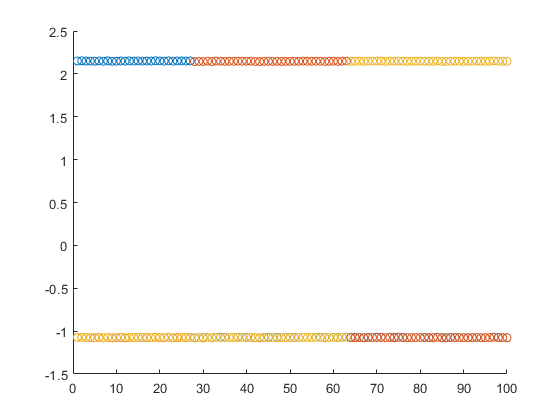


zy = z1; % B*w;
ay = p1;

zet=[];
zet(indexes(1:batchsize),:)=zy(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

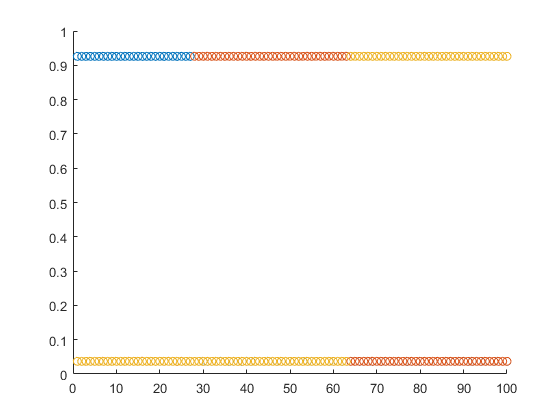


zet=[];
zet(indexes(1:batchsize),:)=ay(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[];
N_a=zeros(batchsize,knots+2);
N_b=zeros(batchsize,knots+2);
N_c=zeros(batchsize,knots+2);
N_d=zeros(batchsize,knots+2);
for i = 1:50

     testindex_a(i)= floor((testinput(i,1)*knots+(10*knots*eps)))+1;
     testindex_b(i)= floor((testinput(i,2)*knots+(10*knots*eps)))+1;
     testindex_c(i)= floor((testinput(i,3)*knots+(10*knots*eps)))+1;
     testindex_d(i)= floor((testinput(i,4)*knots+(10*knots*eps)))+1;
    
    Ntemp_a = (mod(testinput(i,1),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_b = (mod(testinput(i,2),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_c = (mod(testinput(i,3),1/knots)*knots).^linspace(2,0,3)*M';
    Ntemp_d = (mod(testinput(i,4),1/knots)*knots).^linspace(2,0,3)*M';
    
    N_a(i,testindex_a(i):testindex_a(i)+2) = Ntemp_a;
    N_b(i,testindex_b(i):testindex_b(i)+2) = Ntemp_b;
    N_c(i,testindex_c(i):testindex_c(i)+2) = Ntemp_c;
    N_d(i,testindex_d(i):testindex_d(i)+2) = Ntemp_d;
  
f= outproduct( N_a(i,:), N_b(i,:), N_c(i,:), N_d(i,:));
    
Btest(i,:)=f(:)';

end



% zytest = Btest*recon(:);

zytest = Btest*w;
exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexes((end-49):end)));

The construct "indexes(...end...)" is ambiguous in this context, because "indexes" cannot be ascertained to be either the name of a variable or of a function.  To make it a variable, assign to it; to allow it to become a function at execution time, replace "end" with a call to LENGTH, SIZE, or NUMEL on the desired array.

sum(abs(misclassif))/50
sum(abs(pytest-testoutput), 'all')/(150)

C = confusionmat(I,ic(indexes((end-49):end)))
confusionchart(C);

% scatter(1:50,misclassif);

zet=[];
zet(indexes((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:50,zet(:,1))
hold on
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off


% rataa = norm(y-output)/norm(output)



wplot = reshape(w(:,1),(knots+2)*[1 1 1 1])

% surf(1:knots+1,1:knots+2,wplot(:,:,1,1))
% surf(input(:,1),input(:,2),double(rehape(y(:,1), []))

xx=in(:,1)
yy=in(:,2)
zz=double((out(:,3)))
scatter3(xx,yy,zz)

zz=double((output(:,3)))
zz=p1(:,3)

% zz=input(:,3)
% plot3(xx,yy,zz,'.-')
scatter3(xx,yy,zz)


ii=1
for re = logspace(-10,-0.5)
[G, rk] = ttsvd(wplot,re)
suz=0
for k=1:4
    suz = suz + numel(G{k});
end

numberelements = numel(wplot)

numberelements/suz
recon = tcontract(G);


ploto(ii) = sum(abs(recon-wplot),'all')/numberelements

plotosuz(ii)=suz
ii=ii+1;
end

plot(ploto)
plot(plotosuz)